# Linear and quadratic discriminants

For the binary classification problem, if we model each of the two classes by a multivariate Gaussian distribution, then the best discriminant will be either linear or quadratic. We'll illustrate this best discriminant in a few different cases.

Set the prior probabilities of each of the two classes.

p1  = 0.5;
p2  = 1 - p1;

Set the means of the two classes.

mu1 = [-4; 0];
mu2 = [4; 0];

We'll now look at several cases for the covariance matrices, `Sigma1` and `Sigma2`, of the two classes. We'll plot the best discriminant for each case. The `plot_discriminant` function is defined below, which also plots the 95% confidence ellipse and a few samples from each class.

Sigma1  = [2 -1; -1 2]

Sigma1 =      2    -1
    -1     2


Sigma2  = [2 -1; -1 2]

Sigma2 =      2    -1
    -1     2


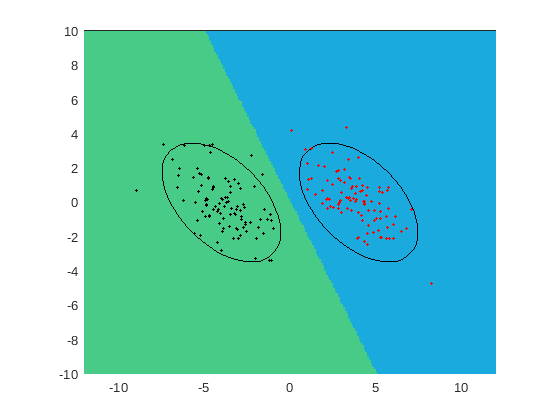

plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2);


Sigma1  = [1  0;  0 1]

Sigma1 =      1     0
     0     1


Sigma2  = [2  1;  1 2]

Sigma2 =      2     1
     1     2


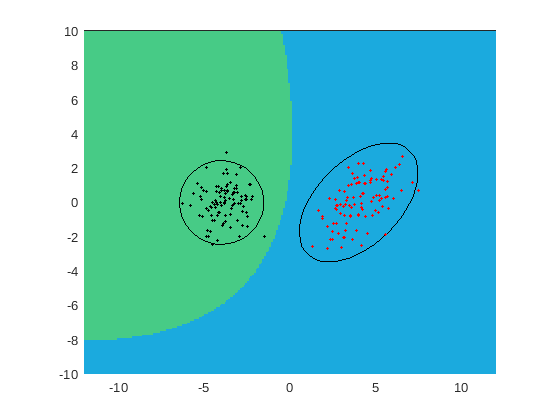

plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2);


Sigma1  = [.1  0;  0 2]

Sigma1 =     0.1000         0
         0    2.0000


Sigma2  = [2  0;  0 .1]

Sigma2 =     2.0000         0
         0    0.1000


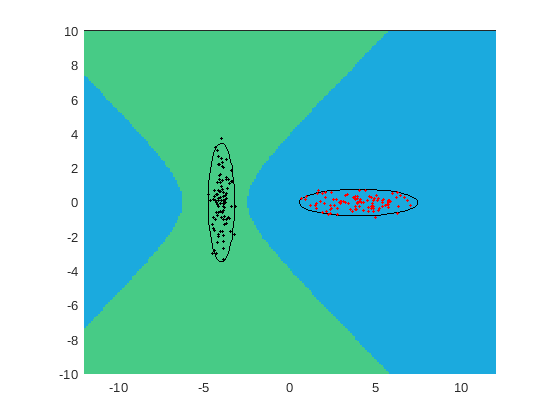

plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2);


Sigma1  = [2 -1; -1 2]

Sigma1 =      2    -1
    -1     2


Sigma2  = [2  1;  1 2]*0.1

Sigma2 =     0.2000    0.1000
    0.1000    0.2000


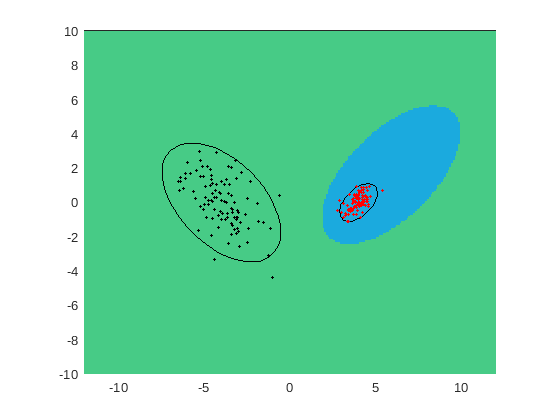

plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2);


Sigma1  = [1  0;  0 1]

Sigma1 =      1     0
     0     1


Sigma2  = [1  0;  0 1]*0.2

Sigma2 =     0.2000         0
         0    0.2000


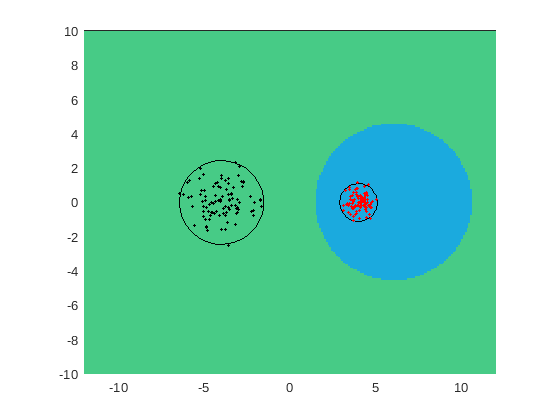

plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2);


Sigma1  = [2 -1; -1 2]

Sigma1 =      2    -1
    -1     2


Sigma2  = [2  1;  1 2]

Sigma2 =      2     1
     1     2


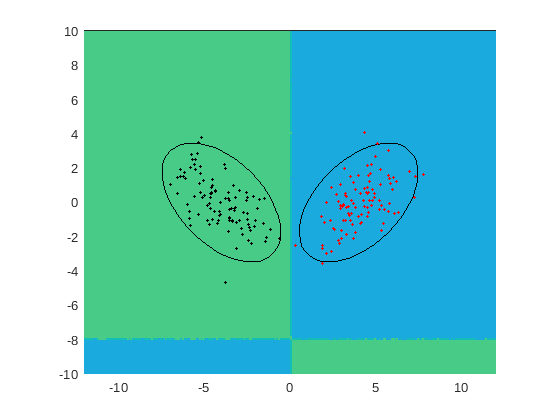

plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2);

We observe that the discriminant can be a straight line, a circle, an ellipse, a parabola, or a hyperbola. It can even be composed of more than one straight line, as shown in the last case above.

The following function computes and plots the discriminant function corresponding to two classes, each modeled with a Gaussian distribution.

function plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2)

% compute values of the discriminant function on a mesh
xx = -12:.1:12;
yy = -10:.1:10;
Z = zeros(length(yy),length(xx));
invSigma1 = inv(Sigma1);
invSigma2 = inv(Sigma2);
logdetSigma1 = 0.5*log(det(Sigma1));
logdetSigma2 = 0.5*log(det(Sigma2));
for i = 1:length(xx)
for j = 1:length(yy)
  x = [xx(i); yy(j)];
  Z(j,i) = -logdetSigma1 -0.5*(x-mu1)'*invSigma1*(x-mu1) ...
           +logdetSigma2 +0.5*(x-mu2)'*invSigma2*(x-mu2) ...
           + log(p1) - log(p2);
end
end

% plot sign of discriminant function
clf
h = pcolor(xx,yy,sign(Z));
set(h, 'edgecolor', 'none');
caxis([-5 5]);
axis equal
axis tight
hold on

% plot ellipses for each class
plot_ellipse95(mu1, Sigma1);
plot_ellipse95(mu2, Sigma2);

% plot sample data for each class
r = mvnrnd(mu1, Sigma1, 100);
scatter(r(:,1),r(:,2),5,'k','filled');
r = mvnrnd(mu2, Sigma2, 100);
scatter(r(:,1),r(:,2),5,'r','filled');
end

The following function plots the 95% confidence ellipse for a Gaussian distribution.

function plot_ellipse95(mu, Sigma)
[V, D] = eig(Sigma);
theta = linspace(0, 2*pi, 50)';
pointsx = sqrt(5.9912*D(1,1))*cos(theta);
pointsy = sqrt(5.9912*D(2,2))*sin(theta);
angle = atan(V(2,1)/V(1,1));
R = [cos(angle) sin(angle); -sin(angle) cos(angle)];
points = [pointsx pointsy] * R;
plot(points(:,1)+mu(1), points(:,2)+mu(2), 'k');
end

### Taking it further

Experiment with your own choices of the covariance matrices for the two classes. You can also change the means of the distributions and vary the prior distributions. For example, what happens in different cases where the means are the same?

Is it possible to obtain a circular discriminant if one or both of the 95% confidence ellipses are not circular?